### PDE Model of Cdk1 Activation and Propagation

Model Parameters.

consts.scale = 10;

% diffusion constant in micro-m^2 min^-1.
consts.Dp = 600;

% EC50 concentrations in nM.
consts.EC50deg = 32;
consts.EC50cdc25 = 35;
consts.EC50wee1 = 30;

Simulation parameters.

% time duration.
consts.tmax = 300;
consts.del_t = 1;

% x range is from -2000 to 2000.
consts.xrange = 2000;

Solve the system of PDEs.

% define time interval and x-mesh.
tspan = linspace(0, consts.tmax, consts.tmax/consts.del_t);
xmesh = linspace(-1*consts.xrange, consts.xrange, 2*consts.xrange); 
% get PDE functions.
pde_funcs = cdk1_act_inact_dt;
% solve PDE!
sol = pdepe(0, ...
    @pde_funcs.Cdk1_PDE, ...
    @pde_funcs.Cdk1_init, ...
    @pde_funcs.Cdk1_boundaries, ...
    xmesh, tspan, [], consts ...
);
disp("PDEs solved");

PDEs solved


% unpack solutions.
cdk1_act = sol(:,:,1);      % active Cdk1 solution.      
cdk1_inact = sol(:,:,2);    % inactive Cdk1 solution.

### Plot Active Cdk1 concentration as a function of time and position.

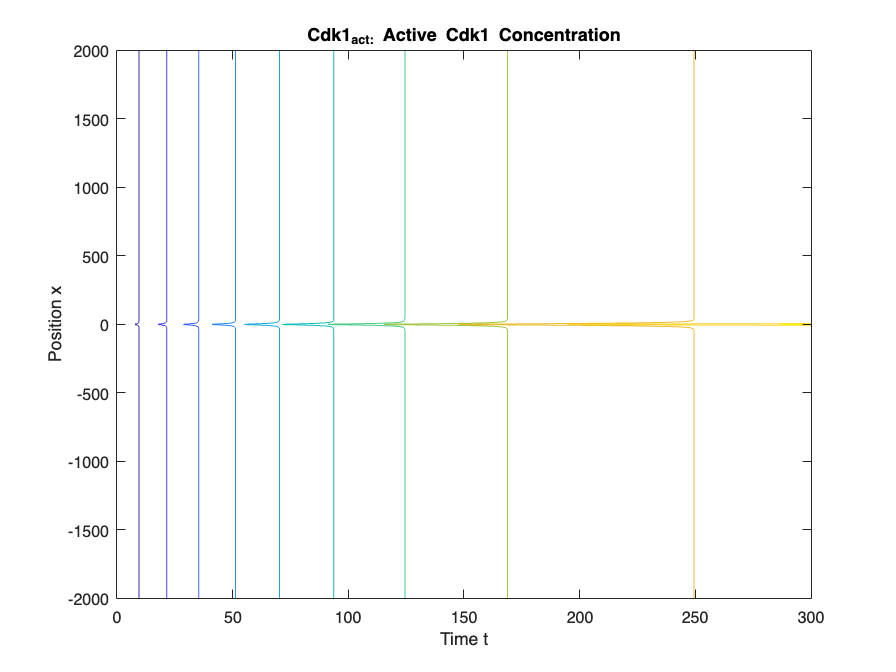

contour(tspan, xmesh, cdk1_act');
title('Cdk1_act: Active Cdk1 Concentration');
xlabel('Time t');
ylabel('Position x');